# Figure 3 on events (with associated supplemental figures)

## PLS plots

d = SessManager.load_special('Mouse2022');
alpha = 0.02;

[X, ks] = d.get_dataset;
X_shuf = shuffle(X, ks);
X_z = zscore(X);
X_shuf_z = zscore(X_shuf);
[XS, stats, origin] =...
    Utils.pls_short(X_z, [ceil(ks/2), mod(ks,2)]);
XS_s = (X_shuf_z - mean(X_shuf_z)) * stats.W;
origin_s = -mean(X_shuf_z) * stats.W;

Using one session from Mouse2022, showing real data:

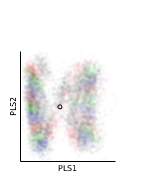

figure;
scatter(XS(:,1), XS(:,2), 8,...
    Utils.colorcode(ceil(ks/2)),...
    'filled', 'MarkerFaceAlpha', alpha);
hold on;
scatter(origin(1), origin(2), 10, 'k');
xlabel PLS1
ylabel PLS2
axis equal; 
axis tight;
xl_ = xlim;
yl_ = ylim;
set(gca, 'XTick', []);
set(gca, 'YTick', []);
figure_format('boxsize', [1 1.2], 'fontsize', 6);
Utils.printto('events_figs/f3_events', 'PLS_events_real.pdf');

And shuffled data:

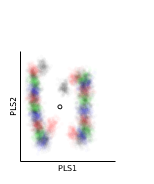

figure;
scatter(XS_s(:,1), XS_s(:,2), 8,...
    Utils.colorcode(ceil(ks/2)),...
    'filled', 'MarkerFaceAlpha', alpha);
hold on;
scatter(origin_s(1), origin_s(2), 10, 'k');
xlabel PLS1;
ylabel PLS2;
axis equal;
axis tight;
xlim(xl_);
ylim(yl_);
set(gca, 'XTick', []);
set(gca, 'YTick', []);
figure_format('boxsize', [1 1.2], 'fontsize', 6);
Utils.printto('events_figs/f3_events', 'PLS_events_shuf.pdf');

## Signal and noise

s_inds = SessManager.special_sessions_usable_index({'Mouse2022', 'Mouse2024', 'Mouse2028'});
get_usable_result = @(idx) load(onefile(['records_adjacent_metrics_events_transients/*_' num2str(idx, '%.3d') '_*']));

res = cell(1,numel(s_inds));
for s_ix = 1:numel(s_inds)
    res{s_ix} = get_usable_result(s_inds(s_ix));
end

cutoff = 100;
asymp_line = @(n,m) Utils.fitaline(n,m,cutoff);
res_lookup = @(res, code)...
    cellfun(@(x)...
    cellfun(@(y)...
    median(y{code(1),code(2:3)}),...
    x.results_table),...
    res,'UniformOutput',false);


n = cellfun(@(x)x.n_sizes, res, 'UniformOutput', false);
signal = res_lookup(res, 'mse');
noise = res_lookup(res, 'mce');
noise_shuf = res_lookup(res, 'mue');

snr = cellfun(@rdivide, signal, noise,...
    'UniformOutput', false);
snr_shuf = cellfun(@rdivide, signal, noise_shuf,...
    'UniformOutput', false);

[signal_slope, signal_slope_conf] = cellfun(asymp_line, n, signal,...
    'UniformOutput', false);
[noise_slope, noise_slope_conf] = cellfun(asymp_line, n, noise,...
    'UniformOutput', false);
[noise_shuf_slope, noise_shuf_slope_conf] = cellfun(asymp_line, n, noise_shuf,...
    'UniformOutput', false);

[asymp_snr, asymp_snr_conf] = cellfun(@uncertain_divide, signal_slope, signal_slope_conf,...
    noise_slope, noise_slope_conf);
[asymp_snr_shuf, asymp_snr_shuf_conf] = cellfun(@uncertain_divide, signal_slope, signal_slope_conf,...
    noise_shuf_slope, noise_shuf_slope_conf);

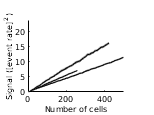

dff2_lim = [0 24];
figure;
MultiSessionVisualizer.plot_single_filtered(n, {signal}, {'k'}, [true true true]);
ylim(dff2_lim);
xlabel 'Number of cells'
ylabel 'Signal ([event rate]^2)'
figure_format([1 0.75]);
Utils.printto('events_figs/f3_events', 'signal_events.pdf');

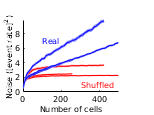


figure;
MultiSessionVisualizer.plot_single_filtered(n, {noise_shuf, noise}, {'r', 'b'}, [true true true]);

text(100, 7, 'Real', 'Color', 'b');
text(300, 1, 'Shuffled', 'Color', 'r');
xlabel 'Number of cells'
ylabel 'Noise ([event rate]^2)'
figure_format([1 0.75]);
Utils.printto('events_figs/f3_events', 'noise_events.pdf');

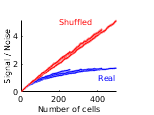


figure;
MultiSessionVisualizer.plot_single_filtered(n, {snr, snr_shuf}, {'b', 'r'}, [true true true]);
text(200, 5, 'Shuffled', 'Color', 'r');
text(400, 1, 'Real', 'Color', 'b');
xlabel 'Number of cells'
ylabel 'Signal / Noise'
figure_format([1 0.75]);
Utils.printto('events_figs/f3_events', 'snr_events.pdf');

#### Supplemental plot showing SNR curves for all sessions

load adjacent_metrics_events_transients_agg_210707-152508_0.mat

res_str = res;
res_cell = cell(1, numel(res));
for i = 1:numel(res_str)
    res_cell{i} = res_str(i);
end
res = res_cell;

cutoff = 100;
asymp_line = @(n,m) Utils.fitaline(n,m,cutoff);
res_lookup = @(res, code)...
    cellfun(@(x)...
    cellfun(@(y)...
    median(y{code(1),code(2:3)}),...
    x.results_table),...
    res,'UniformOutput',false);


n = cellfun(@(x)x.n_sizes, res, 'UniformOutput', false);
signal = res_lookup(res, 'mse');
noise = res_lookup(res, 'mce');
noise_shuf = res_lookup(res, 'mue');

snr = cellfun(@rdivide, signal, noise,...
    'UniformOutput', false);
snr_shuf = cellfun(@rdivide, signal, noise_shuf,...
    'UniformOutput', false);

[signal_slope, signal_slope_conf] = cellfun(asymp_line, n, signal,...
    'UniformOutput', false);
[noise_slope, noise_slope_conf] = cellfun(asymp_line, n, noise,...
    'UniformOutput', false);
[noise_shuf_slope, noise_shuf_slope_conf] = cellfun(asymp_line, n, noise_shuf,...
    'UniformOutput', false);

[asymp_snr, asymp_snr_conf] = cellfun(@uncertain_divide, signal_slope, signal_slope_conf,...
    noise_slope, noise_slope_conf);
[asymp_snr_shuf, asymp_snr_shuf_conf] = cellfun(@uncertain_divide, signal_slope, signal_slope_conf,...
    noise_shuf_slope, noise_shuf_slope_conf);

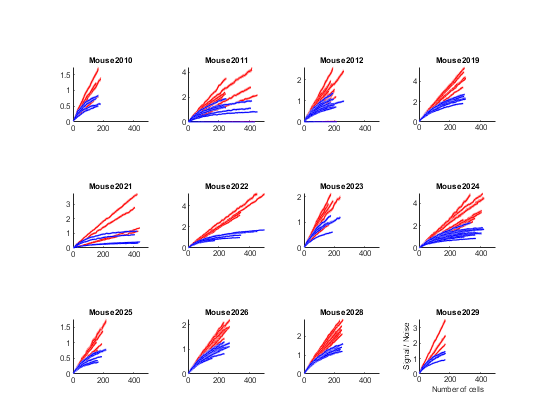

[~, mice_usable] = SessManager.usable_sess_id_list;
figure;
MultiSessionVisualizer.plot_series(n, {snr_shuf, snr}, {'r', 'b'}, mice_usable, [0 Inf]);
xlabel 'Number of cells'
ylabel 'Signal / Noise'
multi_figure_format;
Utils.printto('events_figs/f3_supplements', 'multi_snr_curves.pdf');

figure;
Utils.bns_groupings(asymp_snr, asymp_snr_shuf, asymp_snr_conf, asymp_snr_shuf_conf, mice_usable, false, {'Real', 'Shuffled'}, true);

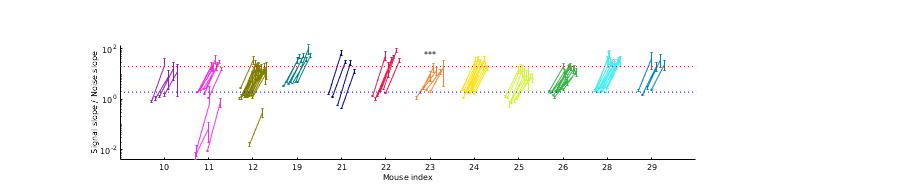

%ylim([min(min(asymp_snr), min(asymp_snr_shuf)),  max(max(asymp_snr), max(asymp_snr_shuf))]);
%ylim([1e-4, 1e4]);
set(gca, 'YTick', [0.01 1 100]);
ylabel(sprintf('Signal slope / Noise slope'));
xlabel 'Mouse index'
Utils.specific_format('MBNS');
Utils.printto('events_figs/f3_supplements', 'multi_asymp_snr.pdf');

### Path analysis between decoding parameters and SNR

var_names = {'asymp_snr', 'single_dp2', 'I0', 'I0N'};

org = Org; org.init;

for i = 1:numel(var_names)
    vars_raw{i} = org.sess_prop.(var_names{i});
    vars_conf{i} = org.sess_prop_conf.(var_names{i});
end

g_ = SessManager.highqual_filt_from_usable.';
%f_ = g_ & vars_raw{1} > vars_conf{1} &...
%    vars_raw{2} > vars_conf{2} &...
%    vars_raw{3} > vars_conf{3} &...
%    vars_raw{4} > vars_conf{4};

vars = cell2mat(vars_raw);
vars = zscore(vars(g_, :));
z_table = array2table(vars, 'VariableNames', var_names);

g_ = SessManager.highqual_filt_from_usable.';
z_table = array2table(zscore([org.sess_prop.asymp_snr(g_),...
    org.sess_prop.single_dp2(g_),...
    org.sess_prop.I0(g_),...
    org.sess_prop.I0N(g_)]), 'VariableNames', var_names);

#### First path analysis, decoding values --> snr values

interaction between I0 and I0N:

fitlm(z_table, 'I0N ~ I0')

ans = Linear regression model:
    I0N ~ 1 + I0

Estimated Coefficients:
                    Estimate         SE          tStat         pValue  
                   ___________    ________    ___________    __________

    (Intercept)    -2.5629e-17    0.087196    -2.9392e-16             1
    I0                 0.67282    0.087799         7.6631    7.0378e-11


Number of observations: 73, Error degrees of freedom: 71
Root Mean Squared Error: 0.745
R-squared: 0.453,  Adjusted R-Squared: 0.445
F-statistic vs. constant model: 58.7, p-value = 7.04e-11

I0, I0N -> ss_snr

fitlm(z_table, 'single_dp2 ~ I0 + I0N')

ans = Linear regression model:
    single_dp2 ~ 1 + I0 + I0N

Estimated Coefficients:
                    Estimate        SE         tStat         pValue  
                   __________    ________    __________    __________

    (Intercept)    6.9557e-17    0.083211    8.3592e-16             1
    I0                0.62736     0.11325        5.5394    4.9859e-07
    I0N               0.11935     0.11325        1.0538       0.29558


Number of observations: 73, Error degrees of freedom: 70
Root Mean Squared Error: 0.711
R-squared: 0.509,  Adjusted R-Squared: 0.495
F-statistic vs. constant model: 36.2, p-value = 1.59e-11

I0, I0N, ss_snr -> dm_asnr

fitlm(z_table, 'asymp_snr ~ I0 + I0N + single_dp2')

ans = Linear regression model:
    asymp_snr ~ 1 + single_dp2 + I0 + I0N

Estimated Coefficients:
                    Estimate         SE          tStat         pValue  
                   ___________    ________    ___________    __________

    (Intercept)    -2.7169e-16    0.059558    -4.5618e-15             1
    single_dp2         0.37992    0.085548         4.4411    3.3204e-05
    I0                 0.50356    0.097218         5.1797     2.096e-06
    I0N               0.071645    0.081702         0.8769       0.38358


Number of observations: 73, Error degrees of freedom: 69
Root Mean Squared Error: 0.509
R-squared: 0.752,  Adjusted R-Squared: 0.741
F-statistic vs. constant model: 69.7, p-value = 7.65e-21

#### Second path analysis, snr values --> decoding variables

interaction between ss_snr and dm_asnr

fitlm(z_table, 'asymp_snr ~ single_dp2')

ans = Linear regression model:
    asymp_snr ~ 1 + single_dp2

Estimated Coefficients:
                    Estimate         SE          tStat         pValue  
                   ___________    ________    ___________    __________

    (Intercept)    -2.9046e-16    0.074474    -3.9001e-15             1
    single_dp2         0.77507     0.07499         10.336    8.4418e-16


Number of observations: 73, Error degrees of freedom: 71
Root Mean Squared Error: 0.636
R-squared: 0.601,  Adjusted R-Squared: 0.595
F-statistic vs. constant model: 107, p-value = 8.44e-16

ss_snr, dm_asnr -> I0

fitlm(z_table, 'I0 ~ single_dp2 + asymp_snr')

ans = Linear regression model:
    I0 ~ 1 + asymp_snr + single_dp2

Estimated Coefficients:
                    Estimate        SE         tStat         pValue  
                   __________    ________    __________    __________

    (Intercept)    2.1175e-16    0.066486    3.1849e-15             1
    asymp_snr         0.68159     0.10595        6.4332    1.3257e-08
    single_dp2        0.17938     0.10595        1.6931      0.094881


Number of observations: 73, Error degrees of freedom: 70
Root Mean Squared Error: 0.568
R-squared: 0.686,  Adjusted R-Squared: 0.677
F-statistic vs. constant model: 76.6, p-value = 2.39e-18

ss_snr, dm_asnr, I0 -> I0N

fitlm(z_table, 'I0N ~ single_dp2 + asymp_snr + I0')

ans = Linear regression model:
    I0N ~ 1 + asymp_snr + single_dp2 + I0

Estimated Coefficients:
                    Estimate        SE         tStat        pValue  
                   __________    ________    __________    _________

    (Intercept)    1.5987e-17    0.087272    1.8318e-16            1
    asymp_snr         0.15384     0.17543        0.8769      0.38358
    single_dp2       0.070966     0.14189       0.50014      0.61857
    I0                0.49636     0.15689        3.1637    0.0023169


Number of observations: 73, Error degrees of freedom: 69
Root Mean Squared Error: 0.746
R-squared: 0.467,  Adjusted R-Squared: 0.444
F-statistic vs. constant model: 20.2, p-value = 1.72e-09

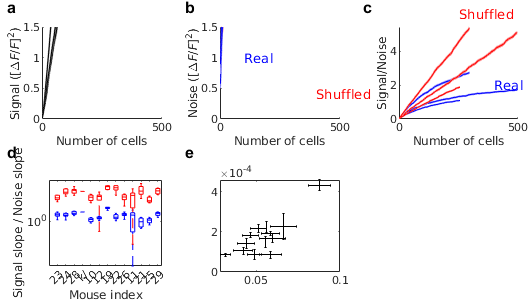

Unable to perform assignment with 0 elements on the right-hand side.

Error in Utils.colorscheme (line 798)
                cs = cs{i};

Error in Utils.names_to_colors (line 812)
                c(i,:) = Utils.colorscheme(index);

Error in DecodeTensor.mcolor (

g_ = SessManager.highqual_filt_from_usable;
dm_asnr = get_asnr(res, s_, 'm', false)'; dm_asnr = zscore(dm_asnr(g_));
%w_asnr = get_asnr(res, s_, 'f', false)'; w_asnr = zscore(w_asnr(g_));
%wd_asnr = get_asnr(res, s_, 'd', false)'; wd_asnr = zscore(wd_asnr(g_));

ss_snr = zscore(single_dp2(g_)');
I0_val = zscore(I0_fit(g_)');
I0N_val = zscore(InfoLimit(g_)');

%% FIRST PATH ANALYSIS - I0 & I0N
%% interaction between I0 and I0N:
fitlm(I0_val, I0N_val)
%% I0, I0N -> ss_snr
fitlm([I0_val, I0N_val], ss_snr)
%% I0, I0N -> dm_asnr
fitlm([I0_val, I0N_val, ss_snr], dm_asnr)
%% SECOND PATH ANALYSIS - ss_snr & dm_asnr
%% interaction between ss_snr and dm_asnr
fitlm(ss_snr, dm_asnr)
%% ss_snr, dm_asnr -> I0
fitlm([ss_snr, dm_asnr], I0_val)
%% ss_snr, dm_asnr, I0_val -> I0N_val
fitlm([ss_snr, dm_asnr, I0_val], I0N_val)

org = Org;
org.init;

fname_save = 'eigen_snr_crossval_save.mat';
if ~exist(fname_save, 'file')
    NU = sm.num_usable;
    WaitMessage = parfor_wait(NU);
    [dp2_train, dp2_test, signal_train, signal_test, noise_train, noise_test] = deal(cell(1,NU));
    parfor i = 1:NU
        cloud = Cloud(i);
        [dp2_train{i}, dp2_test{i},...
            signal_train{i}, signal_test{i},...
            noise_train{i}, noise_test{i}] = cloud.eigen_snr_crossval;
        WaitMessage.Send;
    end
    WaitMessage.Destroy;
    save eigen_snr_crossval_save.mat dp2_train dp2_test signal_train signal_test noise_train noise_test
end

p = Pub(14, 8, 'rows', 2, 'columns', 3, 'start_char', 'f');

%3f
p.panel(1,...
    'xlab', 'Mouse name (Mouse20XX)',...
    'ylab', 'Asymptotic SNR');
org.boxplot('asymp_snr', 'asymp_snr_shuf', true, false);


%3g
p.panel(2,...
    'xlab', 'Single-cell SNR',...
    'ylab', '{\itI}_0 fit value (cm^{-2}\cdotneurons^{-1})');
org.correlogram('single_dp2', 'I0', true, true);

Using only 73 out of 110 sessions
Mouse-aggregated correlations single_dp2 vs. I0: adj. R^2 = 0.729
Pearson: 0.871, p = 1.024996e-03, **
Spearman: 0.564, p = 9.579157e-02, n.s
Kendall: 0.467, p = 7.255015e-02, n.s


p.format;
Utils.fix_exponent(gca, 'y', 1);

%3h
p.panel(3,...
    'xlab', 'Asymptotic SNR',...
    'ylab', sprintf('Asymptotic fit IMSE (cm^{-2})'));
org.correlogram('asymp_snr', 'I0N', true, true);

Using only 73 out of 110 sessions
Mouse-aggregated correlations asymp_snr vs. I0N: adj. R^2 = 0.876
Pearson: 0.943, p = 4.193936e-05, ***
Spearman: 0.891, p = 1.380267e-03, **
Kendall: 0.778, p = 9.463183e-04, ***



%3i
p.panel(4,...
    'xlab', 'PC index',...
    'ylab', 'Eigenmode SNR');
org.eigen_snr_crossval_aggregation(true);

Sum of dp2 from 1 to 6 (the max) = 0.332688
 which is 8.381813% of the total 3.969170


ylim([0 0.11]);

MAX_DIM = 30;
%3j
p.panel(5,...
    'xlab', 'PC index',...
    'ylab', 'cos^2(PC_i, \Delta\mu)');
org.area_between_cos2(MAX_DIM);

%3k
p.panel(6,...
    'xlab', sprintf('Area between PC_{[1-%d]}', MAX_DIM),...
    'ylab', '1/{\itN} fit value (neurons^{-1})');
name = sprintf('delta_cos2_area_%d', MAX_DIM);
org.correlogram(name, 'invN50', true, true, true);

Using only 70 out of 110 sessions
Mouse-aggregated correlations delta_cos2_area_30 vs. invN50: adj. R^2 = 0.259
Pearson: 0.584, p = 7.631673e-02, n.s
Spearman: 0.515, p = 1.328231e-01, n.s
Kendall: 0.378, p = 1.557418e-01, n.s


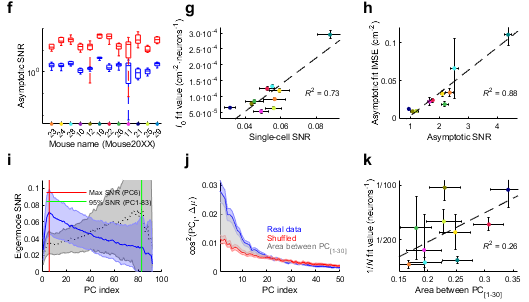

Nvals = [200 100 65 50];
Nlabels = arrayfun(@(x)['1/' num2str(x)],Nvals,'UniformOutput',false);
set(gca, 'YTick', 1./Nvals);
set(gca, 'YTickLabels', Nlabels);

p.format;
p.print('events_figs/f3_events', 'f3_second_half', true);

%savefig('f3_update');

p = Pub(14, 8, 'rows', 2, 'columns', 3, 'start_char', 'f');


%3f
p.panel(1,...
    'xlab', 'Mouse name (Mouse20XX)',...
    'ylab', 'Asymptotic SNR');
org.boxplot('asymp_snr', 'asymp_snr_shuf', true, false);


%3g
p.panel(2,...
    'xlab', 'Single-cell SNR',...
    'ylab', '{\itI}_0 fit value (cm^{-2}\cdotneurons^{-1})');
org.correlogram('single_dp2', 'I0', true, true);

Using only 73 out of 110 sessions
Mouse-aggregated correlations single_dp2 vs. I0: adj. R^2 = 0.730
Pearson: 0.872, p = 1.011597e-03, **
Spearman: 0.564, p = 9.579157e-02, n.s
Kendall: 0.467, p = 7.255015e-02, n.s


p.format;
Utils.fix_exponent(gca, 'y', 1);

%3h
p.panel(3,...
    'xlab', 'Asymptotic SNR',...
    'ylab', sprintf('Asymptotic fit IMSE (cm^{-2})'));
org.correlogram('asymp_snr', 'I0N', true, true);

Using only 73 out of 110 sessions
Mouse-aggregated correlations asymp_snr vs. I0N: adj. R^2 = 0.876
Pearson: 0.943, p = 4.193936e-05, ***
Spearman: 0.891, p = 1.380267e-03, **
Kendall: 0.778, p = 9.463183e-04, ***



%3i
p.panel(4,...
    'xlab', 'PC index',...
    'ylab', 'Eigenmode SNR');
org.eigen_snr_crossval_aggregation(true);

Sum of dp2 from 1 to 6 (the max) = 0.332688
 which is 8.381813% of the total 3.969170


ylim([0 0.11]);


%3j
p.panel(5,...
    'xlab', 'corr. PC index',...
    'ylab', 'cos^2(corr. PC_i, \Delta\mu)');
%org.area_between_cos2(24);
MAX_DIM = 50;
[cl2, cl2_sem] = org.all_med_bins('corr_loadings2', 'restrict');
[cl2_s, cl2_s_sem] = org.all_med_bins('corr_loadings_shuf2', 'restrict');
%[cl2, cl2_sem] = org.all_med_bins('loadings2', 'restrict');
%[cl2_s, cl2_s_sem] = org.all_med_bins('loadings_shuf2', 'restrict');
serrorbar(cl2, cl2_sem*1.96, 'b');
hold on;
serrorbar(cl2_s, cl2_s_sem*1.96, 'r');
patch([1:MAX_DIM, MAX_DIM:-1:1],...
    [cl2(1:MAX_DIM)', cl2_s(MAX_DIM:-1:1)'],...
    [1 1 1]*0.8, 'FaceAlpha', 0.6, 'EdgeColor', 'none');
ylim([0 Inf]);
%xlim([1 50]);
xlim([1 Inf]);
xlabel 'corr. PC index'
ylabel 'cos^2(PC_i, \Delta\mu)'
text(20,0.045/3,'Real data', 'Color', 'b');
text(20,0.035/3,'Shuffled', 'Color', 'r');
text(20, 0.025/3,...
    'Area between all PCs', 'Color', [1 1 1]*0.4);

%3k
MAX_DIM = 83;
p.panel(6,...
    'xlab', 'Area between all PCs',...
    'ylab', '1/{\itN} fit value (neurons^{-1})');
%name = sprintf('corr_delta_cos2_area_%d', MAX_DIM);
%org.correlogram(name, 'invN50', true, true, true);
org.correlogram('corr_cos2_area', 'invN50', true, true, true);

Using only 70 out of 110 sessions
Mouse-aggregated correlations corr_cos2_area vs. invN50: adj. R^2 = 0.575
Pearson: 0.789, p = 6.697114e-03, **
Spearman: 0.770, p = 1.367178e-02, *
Kendall: 0.600, p = 1.666612e-02, *


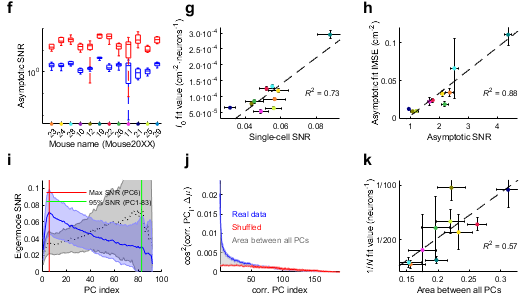

%org.correlogram('cos2_area', 'invN50', true, true, true);
Nvals = [200 100 65 50];
Nlabels = arrayfun(@(x)['1/' num2str(x)],Nvals,'UniformOutput',false);
set(gca, 'YTick', 1./Nvals);
set(gca, 'YTickLabels', Nlabels);

p.format;
p.print('events_figs/f3_events', 'f3_second_half_alt', true);

### Alternative 3k, targeting asymp SNR or asymp IMSE

figure;
org.correlogram('cos2_area', 'asymp_snr', true, true, true);

Using only 73 out of 110 sessions
Mouse-aggregated correlations cos2_area vs. asymp_snr: adj. R^2 = 0.498
Pearson: -0.744, p = 1.362952e-02, *
Spearman: -0.952, p = 0.000000e+00, ***
Kendall: -0.822, p = 3.576940e-04, ***


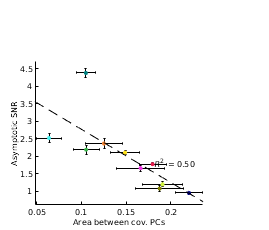

xlabel 'Area between cov. PCs'
ylabel  'Asymptotic SNR'
figure_format([1.75 1.5]);
Utils.printto('events_figs/f3_events', 'f3k_with_asymp_snr.pdf');

figure;
org.correlogram('corr_delta_cos2_area_1', 'asymp_snr', true, true, true);

Using only 73 out of 110 sessions
Mouse-aggregated correlations corr_delta_cos2_area_1 vs. asymp_snr: adj. R^2 = 0.424
Pearson: -0.699, p = 2.458638e-02, *
Spearman: -0.624, p = 6.024898e-02, n.s
Kendall: -0.467, p = 7.255015e-02, n.s


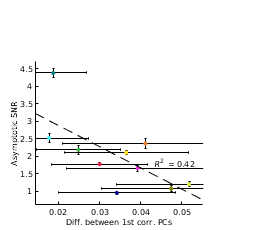

xlabel 'Diff. between 1st corr. PCs'
ylabel  'Asymptotic SNR'
figure_format([1.75 1.5]);
Utils.printto('events_figs/f3_events', 'f3k_with_asymp_snr_PC1.pdf');

## Figure 4 stuff (move to separate file later)

%{
figure;
org.correlogram('signal_density', 'asymp_ratio', true, true, true);
xlabel PSS
ylabel(sprintf('SNR-asymptote ensemble\n____________________________________\nSNR-asymptote ensemble (shuff.)'));
axis square
Utils.printto('events_figs/f4_events', 'pss_snr_ratio_correlation.pdf');

figure;
org.correlogram('dmu_ipr', 'inv_asymp_ratio', true, true, true);
xlabel 'Effective number of coding neurons'
ylabel 'Shuffled asymp. SNR / Real asymp. SNR'
axis square
Utils.printto('events_figs/f4_events', 'number_snr_ratio_correlation.pdf');

Passes a path analysis with number of neurons:

fitlm([zscore(org.sess_prop.num_neurons), zscore(org.sess_prop.dmu_ipr)], zscore(org.sess_prop.inv_asymp_ratio))

figure;

subplot(2,2,1);
mouse_name = 'Mouse2022';
[m,s]=org.mouse_by_bins('signal_density', {mouse_name, 'restrict'});
mean_sig_dens = nanmean(m);
serrorbar(1:20, m(1:20),s(1:20)*1.96);
ax=gca;
ax.XTick = [10 20];
ax.XTickLabel={'L/2','L'};
ylim([0 0.2]);
ylabel PSS
m_color = DecodeTensor.mcolor({mouse_name});
m_color = m_color{1};
text(5, 0.18, mouse_name, 'Color', m_color);
l_ = refline(0, mean_sig_dens);
l_.Color = [0.3 0.3 0.3];
l_.LineStyle = '--';
xlabel 'Running right'

subplot(2,2,2);
serrorbar(1:20, m(21:40),s(21:40)*1.96);
l_ = refline(0, mean_sig_dens);
l_.Color = [0.3 0.3 0.3];
l_.LineStyle = '--';
ylim([0 0.2]);
ax=gca;
ax.XTick=[10 20];
ax.XTickLabel={'L/2','L'};
ax.YAxis.Visible = 'off';
xlabel 'Running left'



subplot(2,2,3);
mouse_name = 'Mouse2024';
[m,s]=org.mouse_by_bins('signal_density', {mouse_name, 'restrict'});
mean_sig_dens = nanmean(m);
serrorbar(1:20, m(1:20),s(1:20)*1.96);
ax = gca;
ax.XTick = [10 20];
ax.XTickLabel = {'L/2', 'L'};
ylim([0 0.2]);
ylabel PSS
m_color = DecodeTensor.mcolor({mouse_name});
m_color = m_color{1};
text(5, 0.15, mouse_name, 'Color', m_color);
l_ = refline(0, mean_sig_dens);
l_.Color = [0.3 0.3 0.3];
l_.LineStyle = '--';
xlabel 'Running right'

subplot(2,2,4);
serrorbar(1:20, m(21:40),s(21:40)*1.96);
l_ = refline(0, mean_sig_dens);
l_.Color = [0.3 0.3 0.3];
l_.LineStyle = '--';
ylim([0 0.2]);
ax=gca;
ax.XTick=[10 20];
ax.XTickLabel={'L/2','L'};
ax.YAxis.Visible = 'off';
xlabel 'Running left'
Utils.printto('events_figs/f4_events', 'pss_by_bin.pdf');

%%
figure;
x_ = org.mouse_all_sess('signal_density', {'Mouse2022', 'restrict'});
x_ = x_(:);
x_(isnan(x_)) = [];

y_ = org.mouse_all_sess('signal_density', {'Mouse2024', 'restrict'});
y_ = y_(:);
y_(isnan(y_)) = [];

bin_width = 0.01;
subplot(2,1,1);
histogram(x_, 'BinWidth', bin_width, 'FaceColor', 'r', 'Normalization', 'probability');
ylabel 'Probability'
axis square;
ax1 = gca;
ax1.Box = 'off';
ax1.XTick = [];
m_color = DecodeTensor.mcolor({'Mouse2022'});
m_color = m_color{1};
text(0.1, 0.2, 'Mouse2022', 'Color', m_color);

subplot(2,1,2);
histogram(y_, 'BinWidth', bin_width, 'FaceColor', 'y', 'Normalization', 'probability');
xlabel 'PSS'
ylabel 'Probability'
axis square;
ax2 = gca;
ax2.Box = 'off';
m_color = DecodeTensor.mcolor({'Mouse2024'});
m_color = m_color{1};
text(0.1, 0.2, 'Mouse2024', 'Color', m_color);
linkaxes([ax1 ax2]);
Utils.printto('events_figs/f4_events', 'pss_histograms.pdf');

figure;

subplot(2,2,1);
mouse_name = 'Mouse2021';
[m,s]=org.mouse_by_bins('dmu_ipr', {mouse_name, 'restrict'});
mean_sig_dens = nanmean(m);
serrorbar(1:20, m(1:20),s(1:20)*1.96);
ax=gca;
ax.XTick = [10 20];
ax.XTickLabel={'L/2','L'};
ylim([0 80]);
ylabel 'Effective # coding neurons'
m_color = DecodeTensor.mcolor({mouse_name});
m_color = m_color{1};
text(5, 70, mouse_name, 'Color', m_color);
l_ = refline(0, mean_sig_dens);
l_.Color = [0.3 0.3 0.3];
l_.LineStyle = '--';
xlabel 'Running right'

subplot(2,2,2);
serrorbar(1:20, m(21:40),s(21:40)*1.96);
l_ = refline(0, mean_sig_dens);
l_.Color = [0.3 0.3 0.3];
l_.LineStyle = '--';
ylim([0 80]);
ax=gca;
ax.XTick=[10 20];
ax.XTickLabel={'L/2','L'};
ax.YAxis.Visible = 'off';
xlabel 'Running left'



subplot(2,2,3);
mouse_name = 'Mouse2026';
[m,s]=org.mouse_by_bins('dmu_ipr', {mouse_name, 'restrict'});
mean_sig_dens = nanmean(m);
serrorbar(1:20, m(1:20),s(1:20)*1.96);
ax = gca;
ax.XTick = [10 20];
ax.XTickLabel = {'L/2', 'L'};
ylim([0 80]);
ylabel 'Effective # coding neurons'
m_color = DecodeTensor.mcolor({mouse_name});
m_color = m_color{1};
text(5, 70, mouse_name, 'Color', m_color);
l_ = refline(0, mean_sig_dens);
l_.Color = [0.3 0.3 0.3];
l_.LineStyle = '--';
xlabel 'Running right'

subplot(2,2,4);
serrorbar(1:20, m(21:40),s(21:40)*1.96);
l_ = refline(0, mean_sig_dens);
l_.Color = [0.3 0.3 0.3];
l_.LineStyle = '--';
ylim([0 80]);
ax=gca;
ax.XTick=[10 20];
ax.XTickLabel={'L/2','L'};
ax.YAxis.Visible = 'off';
xlabel 'Running left'
Utils.printto('events_figs/f4_events', 'number_by_bin.pdf');

%%
figure;
x_ = org.mouse_all_sess('dmu_ipr', {'Mouse2021', 'restrict'});
x_ = x_(:);
x_(isnan(x_)) = [];

y_ = org.mouse_all_sess('dmu_ipr', {'Mouse2026', 'restrict'});
y_ = y_(:);
y_(isnan(y_)) = [];

bin_width = 5;
subplot(2,1,1);

m_color = DecodeTensor.mcolor({'Mouse2021'});
m_color = m_color{1};
text(0.1*500, 0.2, 'Mouse2021', 'Color', m_color); hold on;
histogram(x_, 'BinWidth', bin_width, 'FaceColor', m_color, 'Normalization', 'probability');
ylabel 'Probability'
axis square;
ax1 = gca;
ax1.Box = 'off';
ax1.XTick = [];


subplot(2,1,2);
m_color = DecodeTensor.mcolor({'Mouse2026'});
m_color = m_color{1};
text(0.1*500, 0.2, 'Mouse2026', 'Color', m_color); hold on;
histogram(y_, 'BinWidth', bin_width, 'FaceColor', m_color, 'Normalization', 'probability');
xlabel 'Effective # coding cells'
ylabel 'Probability'
axis square;
ax2 = gca;
ax2.Box = 'off';
linkaxes([ax1 ax2]);
Utils.printto('events_figs/f4_events', 'number_histograms.pdf');
%}

function [quotient, quotient_uncertainty] = uncertain_divide(x, xc, y, yc)
quotient = x./y;
quotient_uncertainty = abs(x./y)*sqrt((xc./x).^2 + (yc./y).^2);
end